# CIC data for simulation

## 1. What data is necessary?

### Flows profile generation

The last item of the **Import** menu in the **Ephemeris** ribbon group allow to generate the **Flows profile files** From geometrical data. Inputs and ouput are CIC-CCSDS files

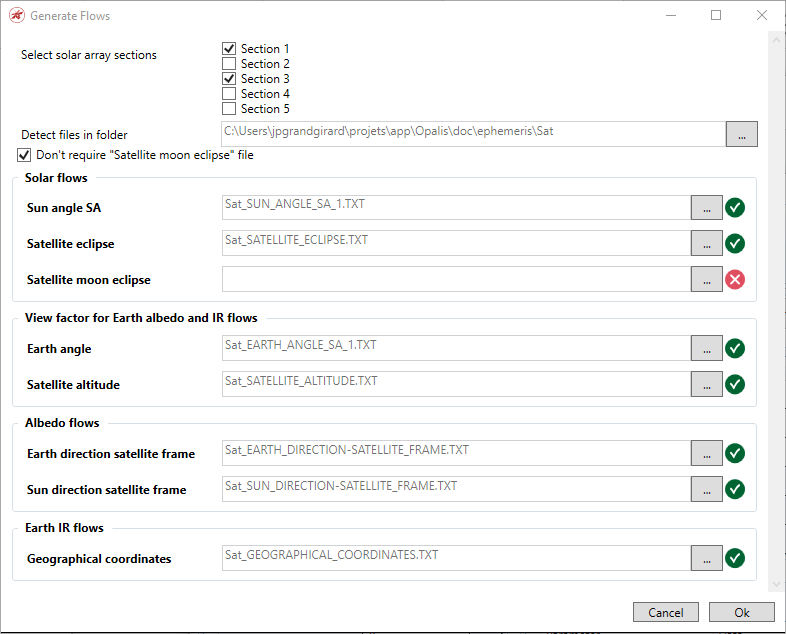

### Files specification

**Sun angle SA (required)**

Standard CIC-CCSDS MEM file with one real data column. The data represents the angle in degrees between the sun direction and the normal of the concidered surface. The default file with the auto detection is the first one with the USER_DEFINED_CONTENT defined by SUN_ANGLE_SA_1.

**Satellite eclipse (required)**

Standard CIC-CCSDS MEM file with one real data column. The data represents the eclipse ratio of the satellite (0.0 : 0% eclipsed, 1.0: 100% eclipsed (umbra)). This ratio considers only the earth. The default file with the auto detection is the first one with the USER_DEFINED_CONTENT defined by SATELLITE_ECLIPSE.

**Satellite moon eclipse (optional)**

Standard CIC-CCSDS MEM file with one real data column. The data represents the eclipse ratio of the satellite (0.0 : 0% eclipsed, 1.0: 100% eclipsed (umbra)). This ratio considers only the moon. The default file with the auto detection is the first one with the USER_DEFINED_CONTENT defined by SATELLITE_ECLIPSE_MOON. This file is not required if the *Don’t require “Satellite moon eclipse” file* control is checked.

**Earth angle (required)**

Standard CIC-CCSDS MEM file with one real data column. The data represents the angle in degrees between the earth direction and the normal of the concidered surface. The default file with the auto detection is the first one with the USER_DEFINED_CONTENT defined by EARTH_ANGLE_SA_1.

**Satellite altitude (required)**

Standard CIC-CCSDS MEM file with one real data column. The data represents the altitude of the satellite in kilometers. The default file with the auto detection is the first one with the USER_DEFINED_CONTENT defined by SATELLITE_ALTITUDE.

**Earth direction satellite frame (required)**

Standard CIC-CCSDS MEM file with 3 real data columns. The data represent the Earth direction (cosine director) in the satellite reference frame The default file with the auto detection is the first one with the USER_DEFINED_CONTENT defined by EARTH_DIRECTION-SATELLITE_FRAME.

**Sun direction satellite frame (required)**

Standard CIC-CCSDS MEM file with 3 real data columns. The data represent the Sun direction (cosine director) in the satellite reference frame The default file with the auto detection is the first one with the USER_DEFINED_CONTENT defined by SUN_DIRECTION-SATELLITE_FRAME.

**Geographical coordinates (required)**

Standard CIC-CCSDS MEM file with 2 real data columns. The data represents the longitude and latitude of the satellite in degrees. The default file with the auto detection is the first one with the USER_DEFINED_CONTENT defined by GEOGRAPHICAL_COORDINATES.

### Power profile file

This file describes the spacecraft power consumption in Watt. This file is used when when **Power consumption mode** is setted to **Profil**.

This file is intended to be a CIC SATELLITE_CONSUMED_POWER standard file but every MEM file with exactly one REAL column can be used.

## 2. Creating the simulink

The simulink file created to generate the data is: ***CICdatapowerfrompropagator.slx***

But first, to initialize it, we need to configure some parameters:

clear
close

%Initialisation of date
date.year=2024;
date.month=9;
date.day=21;
date.hour=12;
date.minutes=0;
date.seconds=0;

%Orbit: Initialisation of Keplerian parameters
orbit.R_earth=6378e3;
orbit.altitude=300e3;
orbit.a = 6678e3;       %semimajor axis [m]
orbit.e = 0.001;        %eccentricity
orbit.i = 98;           %inclination [degrees]
orbit.O = 0;            %Right ascension of the right ascending node [degrees] 
orbit.o = 0;            %Argument of the perigee [degrees]                      
orbit.nu = 0;           %True anomaly [degrees]
%In this case, RAAN=orbit.O is close to the Beta angle.

%time step  
TimeStep = 10;        %fixed-step size in solver, Default time step=0.25
Torbit=2*pi*sqrt((orbit.a/1e3)^3/(3.986004418E5));
N_orbits = 2;           %number of orbits to be simulated
%Time spent performing the simulation in seconds (one orbit is ~5400 s):
%t_sim = N_orbits*Torbit;
t_sim = 48 * 60 * 60; %1 day
MODE=2;

To load the power consumption of the loads:

First, the thruster, the thrust duration is 50 minutes, the heating duration is 16 minutes, it will wait for some time before starting a first cycle, in this case, we set this to 30 minutes. After the thrust has finished, a recharge time can be set. A total waiting time between two cycles would be the sum between the recharge time and the start time. 


$$t_{thrust}=50min=3000s \\
t_{heating}=16min=960s \\
t_{watiting} =t_{recharge}
$$


Also, there is a time before the thrust fires, it is called starting time, but it doesn't affect the calculation.


$$t_{start} = 30min = 1800s $$


There are two duty cycles that are closely related. The thruster duty cycle is the time that the thruster is producing a thrust, this is used for orbit control, orbit propagation, etc.


$$d_{thruster}=\frac{t_{thrust}}{t_{thrust}+t_{heating}+t_{wait}}$$


From the point of view of power consumption, a different duty cycle is used, but this will not be calculated. Only for reference:


$$d_{thruster {_} power}=\frac{t_{thrust}+t_{heating}}{t_{thrust}+t_{heating}+t_{wait}}$$


If the starting time is fixed, then for a desired duty cycle, only the recharge time can be selected.

This can be calculated with:


$$t_{recharge}=\frac{t_{thrust}}{d_{thruster}}-t_{thrust}-t_{heating}$$


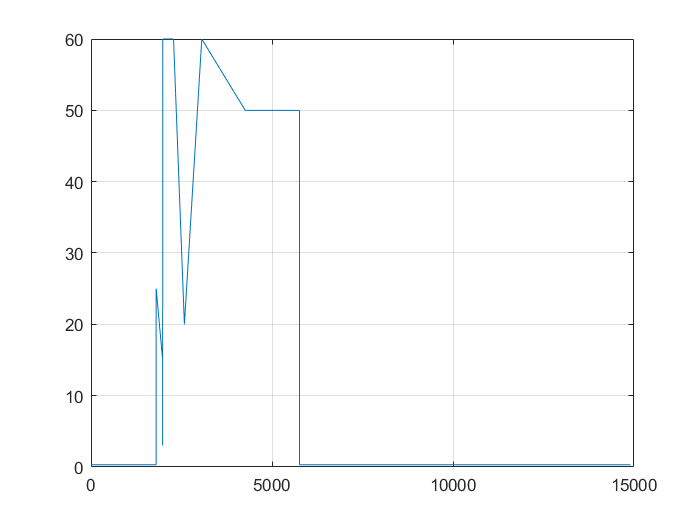

%Thruster required power
Pload1=50;          %Required power Thruster [W]
t0_Th=30*60;        %Time wait before first use of the Thruster;
t_heat=16*60;       %time heating thruster: 16 minutes, in [s]
T_thrust = 50;      %Minutes, total time of thrust (without heating of the thruster)
t_on=T_thrust*60;
%t_rech=27e3;        %time waiting between 2 firings, recharging [seconds], ONLY MODIFY THIS ONE
%Duty_cycle=t_on/(t_on+t_rech+t_heat)*100;  %Duty cycle thrust
%Duty_cycle= 16.25 /100;    %0.1 = 10%
Duty_cycle= 29.41 /100;    %0.1 = 10%
t_rech = (t_on / Duty_cycle) - t_on - t_heat;
t_thr=[0,    t0_Th-1, t0_Th, t0_Th+3*60-1, t0_Th+3*60, t0_Th+3*60+1, t0_Th+8*60, t0_Th+13*60, t0_Th+21*60, t0_Th+41*60, t0_Th+(t_heat/60+T_thrust)*60, t0_Th+(t_heat/60+T_thrust)*60+1, t_on+t_rech+t_heat];
p_thr=[0.32,  0.32,    25,     15,              3,           60,           60,          20,          60,         50,                    50,                      0.32,               0.32];
eff_th=0.95;         %Efficiency power for thruster
figure()
    plot(t_thr,p_thr)
    grid on

%subsystem loads
%P_OBC=2.15;          %Required power OBC [W]
P_OBC=3;          %Required power OBC [W]
eff_OBC=0.94;        %efficiency CH OBC
%ADCS divided in 3 groups
P_ADC=0.55;          %power consumption by sensors and eq. at 3.3V
eff_ADC1=0.6;        %Efficiency CH ADCS 1 3.3V
P_MTQ=1.2;           %power consumption by MTQ at 5V
eff_MTQ=0.91;        %Efficiency CH ADCS 2 5V
%P_RWA=0.6;           %power consumption by sensors and eq. at 3.3V
P_RWA=3.0;           %power consumption by sensors and eq. at 3.3V
eff_RWA=0.9;         %Efficiency CH ADCS 1 3.3V
% Pload3=4.5;          %Required power ADCS w/o RWA [W]
% eff_ADCS=0.92;       %efficiency CH ADCS
%Com subsystem
t0_tx=2.5*Torbit/2+600;    %20 minutes after half orbit [s]
%P_Rx=0.29;          %Required power Com (Rx)[W]
P_Rx=0.42;           %Required power Com (Rx)[W]
%PtxCOM=1.57;        %power if tx every orbit (average)
P_Tx=2.7+P_Rx;       %Peak power UHF [W]
t_wait_Tx=10*Torbit;    %Waiting time before Transmission [s]
p_tx_UHF=[P_Rx P_Rx        P_Tx   P_Tx       P_Rx          P_Rx];
t_tx_UHF=[0    t0_tx-1    t0_tx  t0_tx+600 t0_tx+601    t0_tx+601+t_wait_Tx];
eff_UHF=0.94;        %efficiency CH COM
P_Rx_S=1.5;          %Required power Com S band (Rx) [W]
P_Tx_S=10;           %Peak power Com S band [W]
p_tx_S=[P_Rx_S P_Rx_S   P_Tx_S   P_Tx_S       P_Rx_S      P_Rx_S];
t_tx_S=[0      t0_tx-1  t0_tx    t0_tx+600    t0_tx+601   t0_tx+601+t_wait_Tx];
eff_S=0.98;          %efficiency CH COM
P_GPS=0.225;        %Required power GPS [W]
eff_GPS=0.94;       %efficiency CH GPS
P_heater=2*3;       %Required power heater [W], 2 heaters\

Listed below which loads are active

EN_Thr=1;           %Thruster Enabled=1, disabled=0
EN_OBC=1;           %OBC Enabled=1, disabled=0
EN_ADCS1=1;         %ADCS 3.3V Enabled=1, disabled=0
EN_MTQ=1;           %ADCS 5V Enabled=1, disabled=0
EN_RWA=1;           %ADCS 3.3V Enabled=1, disabled=0
EN_UHF=1;           %TRx UHF enabled=1
EN_S=1;             %S band TP enabled=1
EN_GPS=1;           %GPS Enabled=1, disabled=0
EN_heat=0;          %Heaters batt Enabled=1, disabled=0

To open the simulation:

%CICdatapowerfrompropagator

To get the data out from the simulation:

out=sim('CICdatapowerfrompropagator')

out =   Simulink.SimulationOutput:

            Earth_angle: [1x1 timeseries] 
        Earth_direction: [1x1 timeseries] 
                     LL: [1x1 timeseries] 
           Sun_angle_SA: [1x1 timeseries] 
          Sun_direction: [1x1 timeseries] 
             TOTAL_LOAD: [1x1 timeseries] 
                   T_JD: [1x1 timeseries] 
                    alt: [1x1 timeseries] 
                eclipse: [1x1 timeseries] 
               eclipse1: [1x1 timeseries] 
                   tout: [17281x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


### Converting the data to CIC format

Now we can run the script to convert the data to the CIC format

NOTE: Be sure to be on the folder above the CICData folder where the CIC files will be created.

CIC_writer_EPS

Opening out file
Writing metadata
Writing Sun angle
Writing eclipse fraction
Writing Earth angle
Writing Satellite altitude
Writing Earth direction from Sat.
Writing Sun direction from Sat.
Writing Geographical coordinates
Writing Power loads
Adding data to metadata file
Done!


and finally, copy these files to the OPALIS directory

NOTE: Be sure to be on the folder above the CICData folder where the CIC files were created.

The destination folder can be changed to your own folder.

% copyfile("./CICData/data_earth_angle.txt","C:\CNES\OPALIS\IonSat")
% copyfile("./CICData/data_earth_dir.txt","C:\CNES\OPALIS\IonSat")
% copyfile("./CICData/data_eclipse.txt","C:\CNES\OPALIS\IonSat")
% copyfile("./CICData/data_geo_latlon.txt","C:\CNES\OPALIS\IonSat")
% copyfile("./CICData/data_sat_alt.txt","C:\CNES\OPALIS\IonSat")
% copyfile("./CICData/data_sun_angle.txt","C:\CNES\OPALIS\IonSat")
% copyfile("./CICData/data_sun_dir.txt","C:\CNES\OPALIS\IonSat")
%copyfile("./CICData/data_p_loads.txt","C:\CNES\OPALIS\IonSat")

## 3. Simulation in OPALIS

This is not done in Matlab

In Opalis the following configuration was chosen: